close all;
clear all;
clc;


NORMAS

H = 40; Theta = 5.352*pi/180; L = 65; E = 10; 

M_in = 2; P_in = 101325; Rho_in = 1.225; 
R_air = 287; Gamma = 1.4; T_in = P_in/(Rho_in*R_air); 
a_in = sqrt(Gamma*R_air*T_in); v_in = 0; 
u_in = M_in*a_in; M_angle = asin(1/M_in);


CELDA

Celda = struct('M',zeros(divisiones_xi,divisiones_eta),'u',zeros(divisiones_xi,divisiones_eta),'v',zeros(divisiones_xi,divisiones_eta),'T',zeros(divisiones_xi,divisiones_eta),'P',zeros(divisiones_xi,divisiones_eta),'Rho',zeros(divisiones_xi,divisiones_eta),'a',zeros(divisiones_xi,divisiones_eta),'M_angle',zeros(divisiones_xi,divisiones_eta));
F = struct('F1',zeros(divisiones_xi,divisiones_eta),'F2',zeros(divisiones_xi,divisiones_eta),'F3',zeros(divisiones_xi,divisiones_eta),'F4',zeros(divisiones_xi,divisiones_eta));
G = struct('G1',zeros(divisiones_xi,divisiones_eta),'G2',zeros(divisiones_xi,divisiones_eta),'G3',zeros(divisiones_xi,divisiones_eta),'G4',zeros(divisiones_xi,divisiones_eta));
F_p = struct('F1_p',zeros(divisiones_xi,divisiones_eta),'F2_p',zeros(divisiones_xi,divisiones_eta),'F3_p',zeros(divisiones_xi,divisiones_eta),'F4_p',zeros(divisiones_xi,divisiones_eta));
G_p = struct('G1_p',zeros(divisiones_xi,divisiones_eta),'G2_p',zeros(divisiones_xi,divisiones_eta),'G3_p',zeros(divisiones_xi,divisiones_eta),'G4_p',zeros(divisiones_xi,divisiones_eta));
dF_x = struct('dF1_x',zeros(divisiones_xi,1),'dF2_x',zeros(divisiones_xi,1),'dF3_x',zeros(divisiones_xi,1),'dF4_x',zeros(divisiones_xi,1));
dF_p_x = struct('dF1_p_x',zeros(divisiones_xi,1),'dF2_p_x',zeros(divisiones_xi,1),'dF3_p_x',zeros(divisiones_xi,1),'dF4_p_x',zeros(divisiones_xi,1));
Grid = struct('x',zeros(1,divisiones_eta),'y',zeros(divisiones_xi,divisiones_eta),'y_t',zeros(divisiones_xi,1),'y_s',zeros(1,divisiones_eta),'h',zeros(1,divisiones_eta),'m1',zeros(divisiones_xi,divisiones_eta),'m2',zeros(divisiones_xi,divisiones_eta),'delta_y_t',0.0025);


P_p = zeros(divisiones_xi,1); % for artificial viscosity in the corrector step


MALLA

divisiones_xi=401;
divisiones_eta=877;


i = 1; % Grid horitzontal position (matrix column)
j = 1; % Grid vertical position (matrix row)

Celda.M(:,1) = M_in;
Celda.u(:,1) = u_in;
Celda.v(:,1) = v_in;
Celda.T(:,1) = T_in;
Celda.P(:,1) = P_in;
Celda.Rho(:,1) = Rho_in;
Celda.a(:,1) = a_in;
Celda.M_angle(:,1) = M_angle ; 

F.F1(:,1) = Rho_in*u_in; 
G.G1(:,1) = Rho_in*v_in; 
F.F2(:,1) = Rho_in*(u_in^2) + P_in; 
G.G2(:,1) = Rho_in*u_in*v_in; 
F.F3 = G.G2; 
G.G3(:,1) = Rho_in*(v_in^2) + P_in; 
F.F4(:,1) = (Gamma/(Gamma - 1))*P_in*u_in + Rho_in*u_in*(((u_in^2) + (v_in^2)))/2; 
G.G4(:,1) = (Gamma/(Gamma - 1))*P_in*v_in + Rho_in*v_in*(((u_in^2) + (v_in^2)))/2; 

for j = 2:divisiones_xi 
    Grid.y_t(j) = Grid.y_t(j-1) + Grid.delta_y_t; 
end

COMPUTATION - clase malla

while (Grid.x(i) <= L) 
    % First of all compute the grid transformation for the current (i)
    % position:
    Grid = compute_transformation(i,Grid,H,E,Theta);
     % Compute the downstream step size (delta_x):
    delta_x = compute_step_size(Theta,i,Grid.y,Celda.M_angle);
     % Apply predictor step and obtain the derivatives of F with respect to
    % x and the predicted values of F in i+1:
    [dF_x,F_p] = predictor_step(i,F,G,Grid,F_p,dF_x,Celda.P,delta_x);
    % Obtain the predicted G and P values in i+1:
    [P_p,G_p] = compute_predicted_G(F_p,G_p,P_p,Gamma,i);
     % Now we are able to apply corrector step in oder to obtain the desired values
    % of F at the next downstream point i+1:
    F = corrector_step(i,F,F_p,G_p,P_p,dF_x,dF_p_x,Grid,delta_x);
    % The last step is to decode the flow field variables at i+1 and
    % compute the new G values. This function also includes the application
    % of Abbett's boundary condition for j = 1:
    [Celda,G] = decode_flow_field(i,F,G,Celda,Grid,Gamma,R_air,Theta,E);
    % Finally advance to the next downstream position
    Grid.x(i+1) = Grid.x(i) + delta_x;
    i = i + 1;
    clc;
    fprintf('Step %d of divisiones_eta\n',i);
    
end

Step 2 of 877
Step 3 of 877
Step 4 of 877
Step 5 of 877
Step 6 of 877
Step 7 of 877
Step 8 of 877
Step 9 of 877
Step 10 of 877
Step 11 of 877
Step 12 of 877
Step 13 of 877
Step 14 of 877
Step 15 of 877
Step 16 of 877
Step 17 of 877
Step 18 of 877
Step 19 of 877
Step 20 of 877
Step 21 of 877
Step 22 of 877
Step 23 of 877
Step 24 of 877
Step 25 of 877
Step 26 of 877
Step 27 of 877
Step 28 of 877
Step 29 of 877
Step 30 of 877
Step 31 of 877
Step 32 of 877
Step 33 of 877
Step 34 of 877
Step 35 of 877
Step 36 of 877
Step 37 of 877
Step 38 of 877
Step 39 of 877
Step 40 of 877
Step 41 of 877
Step 42 of 877
Step 43 of 877
Step 44 of 877
Step 45 of 877
Step 46 of 877
Step 47 of 877
Step 48 of 877
Step 49 of 877
Step 50 of 877
Step 51 of 877
Step 52 of 877
Step 53 of 877
Step 54 of 877
Step 55 of 877
Step 56 of 877
Step 57 of 877
Step 58 of 877
Step 59 of 877
Step 60 of 877
Step 61 of 877
Step 62 of 877
Step 63 of 877
Step 64 of 877
Step 65 of 877
Step 66 of 877
Step 67 of 877
Step 68 of 877
Ste


Grid = compute_transformation(i,Grid,H,E,Theta); % To compute the grid transformation at the last point (i = divisiones_eta)

disp('Finished!');

Finished!


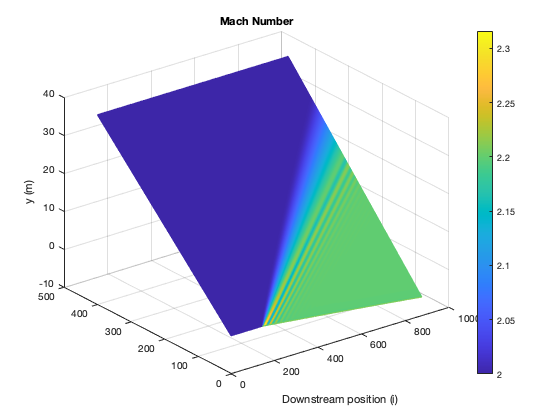


mesh(Grid.y,Celda.M); % Mesh function plots in 3D, but this has no sense in this simulation. Move the axes to view it in 2d.
xlabel('Downstream position (i)');
zlabel('y (m)');
title('Mach Number');
colorbar;

FUNCIONES - clase celda 

function [Updated_Grid] = compute_transformation(i,Grid,H,E,Theta) 
    if (Grid.x(i) < E)
        Grid.y_s(i) = 0;
        Grid.h(i) = H;   
    elseif (Grid.x(i) >= E)
        Grid.y_s(i) = (-Grid.x(i)*tan(Theta)) + (E*tan(Theta));
        Grid.h(i) = H + (Grid.x(i)*tan(Theta)) - (E*tan(Theta));
    end
    for j = 1:divisiones_xi
        if (Grid.x(i) < E)
            Grid.m1(j,i) = 0;
        elseif (Grid.x(i) > E)
            Grid.m1(j,i) = (tan(Theta)/Grid.h(i)) - (Grid.y_t(j)*(tan(Theta)/Grid.h(i)));
        end
        Grid.y(j,i) = (Grid.y_t(j)*Grid.h(i)) + Grid.y_s(i);
        Grid.m2(j,i) = 1/Grid.h(i);
    end
    Updated_Grid = Grid;
end

function [delta_x] = compute_step_size(Theta,i,y,M_angle) 
    tan_max_pos = 0;
    tan_max_neg = 0;
    for j = 1:divisiones_xi
        tan_pos = abs(tan(Theta+M_angle(j,i)));
        tan_neg = abs(tan(Theta-M_angle(j,i)));
        if (tan_pos > tan_max_pos)
            tan_max_pos = tan_pos;
        end
        if (tan_neg > tan_max_neg)
            tan_max_neg = tan_neg;
        end
    end
    tan_max = max(tan_max_pos,tan_max_neg);
    delta_y = y(2,i) - y(1,i);  
    delta_x = 0.5*(delta_y/tan_max); 
end

function [Updated_derivatives, Predicted_F_values] = predictor_step(i,F,G,Grid,F_p,dF_x,P,delta_x) 
    for j = 1:divisiones_xi
        if (j == 1) % Forward difference without artificial viscosity (no artificial viscosity in the boundaries)
            dF_x.dF1_x(j) = (Grid.m1(j,i)*((F.F1(j,i) - F.F1(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G1(j,i) - G.G1(j+1,i))/Grid.delta_y_t)); % The derivative of F1 with respect to x (Xi) at the point j,i
            dF_x.dF2_x(j) = (Grid.m1(j,i)*((F.F2(j,i) - F.F2(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G2(j,i) - G.G2(j+1,i))/Grid.delta_y_t));
            dF_x.dF3_x(j) = (Grid.m1(j,i)*((F.F3(j,i) - F.F3(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G3(j,i) - G.G3(j+1,i))/Grid.delta_y_t));
            dF_x.dF4_x(j) = (Grid.m1(j,i)*((F.F4(j,i) - F.F4(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G4(j,i) - G.G4(j+1,i))/Grid.delta_y_t));
            F_p.F1_p(j,i+1) = F.F1(j,i) + (dF_x.dF1_x(j)*delta_x); % By the Euler numerical method advance F1 to the next downstream point and obtain its predicted value
            F_p.F2_p(j,i+1) = F.F2(j,i) + (dF_x.dF2_x(j)*delta_x);
            F_p.F3_p(j,i+1) = F.F3(j,i) + (dF_x.dF3_x(j)*delta_x);
            F_p.F4_p(j,i+1) = F.F4(j,i) + (dF_x.dF4_x(j)*delta_x);
        elseif (j == divisiones_xi) % Rearward difference without artificial viscosity
            dF_x.dF1_x(j) = (Grid.m1(j,i)*((F.F1(j-1,i) - F.F1(j,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G1(j-1,i) - G.G1(j,i))/Grid.delta_y_t));
            dF_x.dF2_x(j) = (Grid.m1(j,i)*((F.F2(j-1,i) - F.F2(j,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G2(j-1,i) - G.G2(j,i))/Grid.delta_y_t));
            dF_x.dF3_x(j) = (Grid.m1(j,i)*((F.F3(j-1,i) - F.F3(j,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G3(j-1,i) - G.G3(j,i))/Grid.delta_y_t));
            dF_x.dF4_x(j) = (Grid.m1(j,i)*((F.F4(j-1,i) - F.F4(j,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G4(j-1,i) - G.G4(j,i))/Grid.delta_y_t));
            F_p.F1_p(j,i+1) = F.F1(j,i) + (dF_x.dF1_x(j)*delta_x);
            F_p.F2_p(j,i+1) = F.F2(j,i) + (dF_x.dF2_x(j)*delta_x);
            F_p.F3_p(j,i+1) = F.F3(j,i) + (dF_x.dF3_x(j)*delta_x);
            F_p.F4_p(j,i+1) = F.F4(j,i) + (dF_x.dF4_x(j)*delta_x);
        else % Forward difference with artificial viscosity
            dF_x.dF1_x(j) = (Grid.m1(j,i)*((F.F1(j,i) - F.F1(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G1(j,i) - G.G1(j+1,i))/Grid.delta_y_t));
            dF_x.dF2_x(j) = (Grid.m1(j,i)*((F.F2(j,i) - F.F2(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G2(j,i) - G.G2(j+1,i))/Grid.delta_y_t));
            dF_x.dF3_x(j) = (Grid.m1(j,i)*((F.F3(j,i) - F.F3(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G3(j,i) - G.G3(j+1,i))/Grid.delta_y_t));
            dF_x.dF4_x(j) = (Grid.m1(j,i)*((F.F4(j,i) - F.F4(j+1,i))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G.G4(j,i) - G.G4(j+1,i))/Grid.delta_y_t));
            SF1 = ((0.6*(abs((P(j+1,i)) - (2*P(j,i)) + P(j-1,i))))/(P(j+1,i) + 2*P(j,i) + P(j-1,i)))*(F.F1(j+1,i) - (2*F.F1(j,i)) + F.F1(j-1,i)); % Value of artificial viscosity at j,i
            SF2 = ((0.6*(abs((P(j+1,i)) - (2*P(j,i)) + P(j-1,i))))/(P(j+1,i) + 2*P(j,i) + P(j-1,i)))*(F.F2(j+1,i) - (2*F.F2(j,i)) + F.F2(j-1,i));
            SF3 = ((0.6*(abs((P(j+1,i)) - (2*P(j,i)) + P(j-1,i))))/(P(j+1,i) + 2*P(j,i) + P(j-1,i)))*(F.F3(j+1,i) - (2*F.F3(j,i)) + F.F3(j-1,i));
            SF4 = ((0.6*(abs((P(j+1,i)) - (2*P(j,i)) + P(j-1,i))))/(P(j+1,i) + 2*P(j,i) + P(j-1,i)))*(F.F4(j+1,i) - (2*F.F4(j,i)) + F.F4(j-1,i));
            F_p.F1_p(j,i+1) = F.F1(j,i) + (dF_x.dF1_x(j)*delta_x) + SF1;
            F_p.F2_p(j,i+1) = F.F2(j,i) + (dF_x.dF2_x(j)*delta_x) + SF2;
            F_p.F3_p(j,i+1) = F.F3(j,i) + (dF_x.dF3_x(j)*delta_x) + SF3;
            F_p.F4_p(j,i+1) = F.F4(j,i) + (dF_x.dF4_x(j)*delta_x) + SF4;
        end
    end
    Updated_derivatives = dF_x;
    Predicted_F_values = F_p;
end

function [Predicted_pressure_value,Predicted_G_values] = compute_predicted_G(F_p,G_p,P_p,Gamma,i) % clase celda
    for j = 1:divisiones_xi
        A_p = ((F_p.F3_p(j,i+1)^2)/(2*F_p.F1_p(j,i+1))) - F_p.F4_p(j,i+1);
        B_p = (Gamma/(Gamma - 1))*F_p.F1_p(j,i+1)*F_p.F2_p(j,i+1);
        C_p = -(((Gamma + 1)/(2*(Gamma - 1)))*(F_p.F1_p(j,i+1)^3));
        Rho_p = (-B_p + (sqrt((B_p^2) - (4*A_p*C_p))))/(2*A_p);
        P_p(j) = F_p.F2_p(j,i+1) - ((F_p.F1_p(j,i+1)^2)/Rho_p);
        G_p.G1_p(j,i+1) = Rho_p*(F_p.F3_p(j,i+1)/F_p.F1_p(j,i+1));
        G_p.G2_p(j,i+1) = F_p.F3_p(j,i+1);
        G_p.G3_p(j,i+1) = (Rho_p*((F_p.F3_p(j,i+1)/F_p.F1_p(j,i+1))^2)) + F_p.F2_p(j,i+1) - ((F_p.F1_p(j,i+1)^2)/Rho_p);
        G_p.G4_p(j,i+1) = ((Gamma/(Gamma - 1))*((F_p.F2_p(j,i+1)) - ((F_p.F1_p(j,i+1)^2)/Rho_p))*(F_p.F3_p(j,i+1)/F_p.F1_p(j,i+1))) + (((Rho_p*F_p.F3_p(j,i+1))/(2*F_p.F1_p(j,i+1)))*(((F_p.F1_p(j,i+1)/Rho_p)^2) + ((F_p.F3_p(j,i+1)/F_p.F1_p(j,i+1))^2)));
    end
    Predicted_pressure_value = P_p;
    Predicted_G_values = G_p;
end

function [F_values] = corrector_step(i,F,F_p,G_p,P_p,dF_x,dF_p_x,Grid,delta_x) 
    for j = 1:divisiones_xi
        if (j == 1) % Forward difference without artificial viscosity (no artificial viscosity in the boundaries)
            dF_p_x.dF1_p_x(j) = (Grid.m1(j,i)*((F_p.F1_p(j,i+1) - F_p.F1_p(j+1,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G1_p(j,i+1) - G_p.G1_p(j+1,i+1))/Grid.delta_y_t)); % The derivative of F1_p with respect to x (Xi) at the point j,i+1
            dF_p_x.dF2_p_x(j) = (Grid.m1(j,i)*((F_p.F2_p(j,i+1) - F_p.F2_p(j+1,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G2_p(j,i+1) - G_p.G2_p(j+1,i+1))/Grid.delta_y_t));
            dF_p_x.dF3_p_x(j) = (Grid.m1(j,i)*((F_p.F3_p(j,i+1) - F_p.F3_p(j+1,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G3_p(j,i+1) - G_p.G3_p(j+1,i+1))/Grid.delta_y_t));
            dF_p_x.dF4_p_x(j) = (Grid.m1(j,i)*((F_p.F4_p(j,i+1) - F_p.F4_p(j+1,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G4_p(j,i+1) - G_p.G4_p(j+1,i+1))/Grid.delta_y_t));
        elseif (j == divisiones_xi) % Rearward difference without artificial viscosity
            dF_p_x.dF1_p_x(j) = (Grid.m1(j,i)*((F_p.F1_p(j-1,i+1) - F_p.F1_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G1_p(j-1,i+1) - G_p.G1_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF2_p_x(j) = (Grid.m1(j,i)*((F_p.F2_p(j-1,i+1) - F_p.F2_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G2_p(j-1,i+1) - G_p.G2_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF3_p_x(j) = (Grid.m1(j,i)*((F_p.F3_p(j-1,i+1) - F_p.F3_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G3_p(j-1,i+1) - G_p.G3_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF4_p_x(j) = (Grid.m1(j,i)*((F_p.F4_p(j-1,i+1) - F_p.F4_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G4_p(j-1,i+1) - G_p.G4_p(j,i+1))/Grid.delta_y_t));
        else % Rearward difference with artificial viscosity
            dF_p_x.dF1_p_x(j) = (Grid.m1(j,i)*((F_p.F1_p(j-1,i+1) - F_p.F1_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G1_p(j-1,i+1) - G_p.G1_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF2_p_x(j) = (Grid.m1(j,i)*((F_p.F2_p(j-1,i+1) - F_p.F2_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G2_p(j-1,i+1) - G_p.G2_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF3_p_x(j) = (Grid.m1(j,i)*((F_p.F3_p(j-1,i+1) - F_p.F3_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G3_p(j-1,i+1) - G_p.G3_p(j,i+1))/Grid.delta_y_t));
            dF_p_x.dF4_p_x(j) = (Grid.m1(j,i)*((F_p.F4_p(j-1,i+1) - F_p.F4_p(j,i+1))/Grid.delta_y_t)) + (Grid.m2(j,i)*((G_p.G4_p(j-1,i+1) - G_p.G4_p(j,i+1))/Grid.delta_y_t));
        
            SF1_p = (((0.6*(abs(P_p(j+1)) - (2*P_p(j)) + P_p(j-1))))/(P_p(j+1) + 2*P_p(j) + P_p(j-1)))*(F_p.F1_p(j+1,i+1) - (2*F_p.F1_p(j,i+1)) + F_p.F1_p(j-1,i+1)); % Predicted value of artificial viscosity at j,i+1
            SF2_p = (((0.6*(abs(P_p(j+1)) - (2*P_p(j)) + P_p(j-1))))/(P_p(j+1) + 2*P_p(j) + P_p(j-1)))*(F_p.F2_p(j+1,i+1) - (2*F_p.F2_p(j,i+1)) + F_p.F2_p(j-1,i+1));
            SF3_p = (((0.6*(abs(P_p(j+1)) - (2*P_p(j)) + P_p(j-1))))/(P_p(j+1) + 2*P_p(j) + P_p(j-1)))*(F_p.F3_p(j+1,i+1) - (2*F_p.F3_p(j,i+1)) + F_p.F3_p(j-1,i+1));
            SF4_p = (((0.6*(abs(P_p(j+1)) - (2*P_p(j)) + P_p(j-1))))/(P_p(j+1) + 2*P_p(j) + P_p(j-1)))*(F_p.F4_p(j+1,i+1) - (2*F_p.F4_p(j,i+1)) + F_p.F4_p(j-1,i+1));
        end
    
        dF1_x_av = 0.5*(dF_x.dF1_x(j) + dF_p_x.dF1_p_x(j));
        dF2_x_av = 0.5*(dF_x.dF2_x(j) + dF_p_x.dF2_p_x(j));
        dF3_x_av = 0.5*(dF_x.dF3_x(j) + dF_p_x.dF3_p_x(j));
        dF4_x_av = 0.5*(dF_x.dF4_x(j) + dF_p_x.dF4_p_x(j));
        
        if (j == 1 || j == divisiones_xi)
            F.F1(j,i+1) = F.F1(j,i) + (dF1_x_av*delta_x);
            F.F2(j,i+1) = F.F2(j,i) + (dF2_x_av*delta_x);
            F.F3(j,i+1) = F.F3(j,i) + (dF3_x_av*delta_x);
            F.F4(j,i+1) = F.F4(j,i) + (dF4_x_av*delta_x);
        else
            F.F1(j,i+1) = F.F1(j,i) + (dF1_x_av*delta_x) + SF1_p;
            F.F2(j,i+1) = F.F2(j,i) + (dF2_x_av*delta_x) + SF2_p;
            F.F3(j,i+1) = F.F3(j,i) + (dF3_x_av*delta_x) + SF3_p;
            F.F4(j,i+1) = F.F4(j,i) + (dF4_x_av*delta_x) + SF4_p;
        end
    end
    F_values = F;
end

function [Updated_flow_field,Updated_G] = decode_flow_field(i,F,G,Flow_field,Grid,Gamma,R_air,Theta,E)
    for j = 1:divisiones_xi
        A = ((F.F3(j,i+1)^2)/(2*F.F1(j,i+1))) - F.F4(j,i+1);
        B = (Gamma/(Gamma - 1))*F.F1(j,i+1)*F.F2(j,i+1);
        C = -(((Gamma + 1)/(2*(Gamma - 1)))*(F.F1(j,i+1)^3));
        if (j == 1) % Apply Abbett's wall boundary condition
            Rho_cal = (-B + (sqrt((B^2) - (4*A*C))))/(2*A);
            u_cal = F.F1(j,i+1)/Rho_cal;
            v_cal = F.F3(j,i+1)/F.F1(j,i+1);
            P_cal = F.F2(j,i+1) - (F.F1(j,i+1)*u_cal);
            T_cal = P_cal/(R_air*Rho_cal);
            M_cal = (sqrt((u_cal^2) + (v_cal)^2))/(sqrt(Gamma*R_air*T_cal));
            if (Grid.x(i) < E)
                phi = atan(v_cal/u_cal);
            else
                phi = Theta - (atan(abs(v_cal)/u_cal));
            end
            f_cal = sqrt((Gamma + 1)/(Gamma - 1))*(atan(sqrt(((Gamma - 1)/(Gamma + 1))*(M_cal^2 - 1)))) - (atan(sqrt((M_cal^2) - 1))); % Prandtl-Meyer function
            f_act = f_cal + phi; % Rotated Prandtl-Meyer function
        % We need to find the Mach number corresponding to a Prandtl-Meyer
        % function of value "f_act". Anderson suggests a simple trial and
        % error computation, but I have used a bisection method that I think should be
        % more efficient.
            a_int = 1.1; % Left limit of the interval 
            b_int = 2.9; % Right limit of the interval
            precision = 0.0000001; % Max error 
            zero_f1 = sqrt((Gamma + 1)/(Gamma - 1))*(atan(sqrt(((Gamma - 1)/(Gamma + 1))*(a_int^2 - 1)))) - (atan(sqrt((a_int^2) - 1))) - f_act; % Function used to find its zero
            zero_f2 = sqrt((Gamma + 1)/(Gamma - 1))*(atan(sqrt(((Gamma - 1)/(Gamma + 1))*(((a_int + b_int)/2)^2 - 1)))) - (atan(sqrt((((a_int + b_int)/2)^2) - 1))) - f_act;
            while ((b_int-a_int)/2 > precision)
                if (zero_f1*zero_f2 <=0)
                    b_int = (a_int + b_int)/2;
                else
                    a_int = (a_int + b_int)/2;
                end
                zero_f1 = sqrt((Gamma + 1)/(Gamma - 1))*(atan(sqrt(((Gamma - 1)/(Gamma + 1))*(a_int^2 - 1)))) - (atan(sqrt((a_int^2) - 1))) - f_act;
                zero_f2 = sqrt((Gamma + 1)/(Gamma - 1))*(atan(sqrt(((Gamma - 1)/(Gamma + 1))*(((a_int + b_int)/2)^2 - 1)))) - (atan(sqrt((((a_int + b_int)/2)^2) - 1))) - f_act;
            end
            M_act = (a_int + b_int)/2; % Corrected Mach number
            Flow_field.M(j,i+1) = M_act;
            Flow_field.M_angle(j,i+1) = (asin(1/Flow_field.M(j,i+1)));
            Flow_field.P(j,i+1) = P_cal*(((1 + ((Gamma - 1)/2)*(M_cal^2))/(1 + ((Gamma - 1)/2)*(M_act^2)))^(Gamma/(Gamma - 1)));
            Flow_field.T(j,i+1) = T_cal*((1 + ((Gamma - 1)/2)*(M_cal^2))/(1 + ((Gamma - 1)/2)*(M_act^2)));
            Flow_field.Rho(j,i+1) = Flow_field.P(j,i+1)/(R_air*Flow_field.T(j,i+1));
            Flow_field.u(j,i+1) = u_cal;
            Flow_field.a(j,i+1) = sqrt(Gamma*R_air*Flow_field.T(j,i+1));
            if (Grid.x(i) > E)
                Flow_field.v(j,i+1) = -(Flow_field.u(j,i+1)*tan(Theta));
            else
                Flow_field.v(j,i+1) = 0;
            end
        % Finally we correct the F terms
            F.F1(j,i+1) = Flow_field.Rho(j,i+1)*Flow_field.u(j,i+1);
            F.F2(j,i+1) = (Flow_field.Rho(j,i+1)*(Flow_field.u(j,i+1)^2)) + Flow_field.P(j,i+1);
            F.F3(j,i+1) = Flow_field.Rho(j,i+1)*Flow_field.u(j,i+1)*Flow_field.v(j,i+1);
            F.F4(j,i+1) = ((Gamma/(Gamma - 1))*Flow_field.P(j,i+1)*Flow_field.u(j,i+1)) + (Flow_field.Rho(j,i+1)*Flow_field.u(j,i+1)*(((Flow_field.u(j,i+1)^2) + (Flow_field.v(j,i+1)^2)))/2);
        else
            Flow_field.Rho(j,i+1) = (-B + (sqrt((B^2) - (4*A*C))))/(2*A);
            Flow_field.u(j,i+1) = F.F1(j,i+1)/Flow_field.Rho(j,i+1);
            Flow_field.v(j,i+1) = F.F3(j,i+1)/F.F1(j,i+1);
            Flow_field.P(j,i+1) = F.F2(j,i+1) - (F.F1(j,i+1)*Flow_field.u(j,i+1));
            Flow_field.T(j,i+1) = Flow_field.P(j,i+1)/(R_air*Flow_field.Rho(j,i+1));
            Flow_field.a(j,i+1) = sqrt(Gamma*R_air*Flow_field.T(j,i+1));
            Flow_field.M(j,i+1) = (sqrt((Flow_field.u(j,i+1)^2) + (Flow_field.v(j,i+1)^2)))/Flow_field.a(j,i+1);
            Flow_field.M_angle(j,i+1) = asin(1/Flow_field.M(j,i+1));
        end
        G.G1(j,i+1) = Flow_field.Rho(j,i+1)*(F.F3(j,i+1)/F.F1(j,i+1));
        G.G2(j,i+1) = F.F3(j,i+1);
        G.G3(j,i+1) = (Flow_field.Rho(j,i+1)*((F.F3(j,i+1)/F.F1(j,i+1))^2)) + F.F2(j,i+1) - ((F.F1(j,i+1)^2)/Flow_field.Rho(j,i+1));
        G.G4(j,i+1) = ((Gamma/(Gamma - 1))*((F.F2(j,i+1)) - ((F.F1(j,i+1)^2)/Flow_field.Rho(j,i+1)))*(F.F3(j,i+1)/F.F1(j,i+1))) + (((Flow_field.Rho(j,i+1)*F.F3(j,i+1))/(2*F.F1(j,i+1)))*(((F.F1(j,i+1)/Flow_field.Rho(j,i+1))^2) + ((F.F3(j,i+1)/F.F1(j,i+1))^2)));
    end
    Updated_flow_field = Flow_field;
    Updated_G = G;
end